Function fun_04_chassis_wheel_tire: vehicle wheel tire model dynamics  

The equations of motion for the simple vehicle wheel tire model including the

enhanced braking torque model are provided by this function in as a set of first-order differential equations.  .

function [xp,out] = fun_04_chassis_wheel_tire(t,x,p)
% simple vehicle model including wheel and tire dynamics

% get states 
v = x(1); o = x(2);     % Vehicle velocity & angular velocity of wheel 
xe = x(3);  xv = x(4);   % longitudinal tyre deflection & vehicle position 

% actual driving & maximum braking torque via linear interpoletion 
out.tq_D   = interp1(p.t_Drive , p.Drive_Torque , t);
tq_Bmx     = interp1(p.t_Brake , p.Brake_Torque , t);

% modified transport velocity & longitudinal slip without normalization 
vt = abs(p.r * o) + p.vN; vs = v - p.r * o; out.sx = -vs / vt;

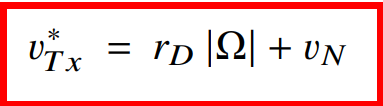 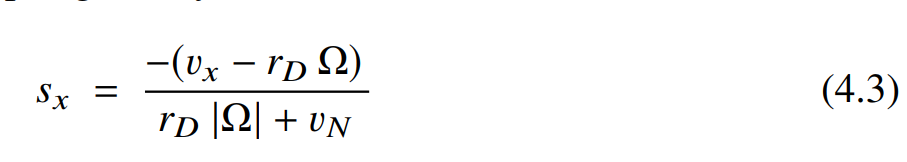

% generalized tyre characteristics (sx only)
[~ , fos] = tmy_fcombined(abs(out.sx) , p.dfx0 , p.fxm , p.sxm , p.fxs , p.sxs);

% time derivative of longitudinal tyre deflection & longtudinal dynamic
% tyre force
xedot = -(p.cx*xe*vt + fos*vs)/(p.dx*vt + fos) ;
out.fxd = p.cx*xe + p.dx*xedot;

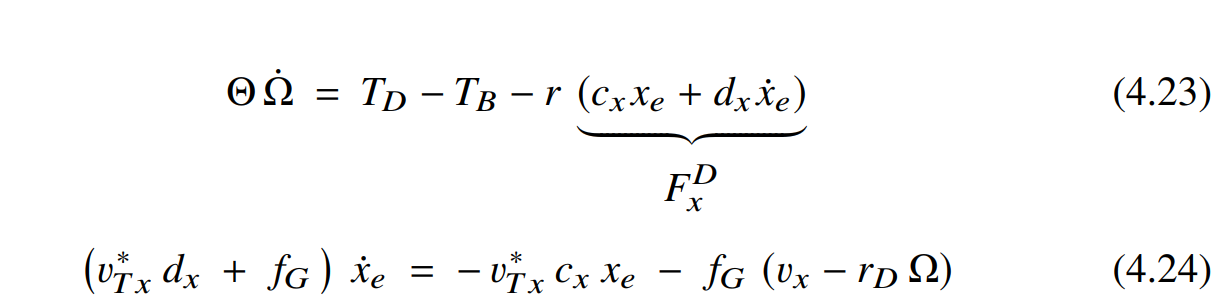 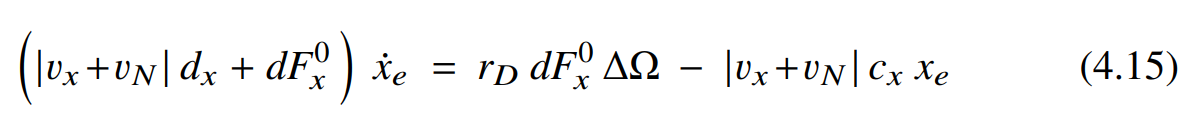

% applied braking torque (Enhanced dry friction model)
out.tq_B = out.tq_D - p.r*out.fxd + p.dN*o;
out.tq_B = sign(out.tq_B)*min(abs(out.tq_B) , tq_Bmx);

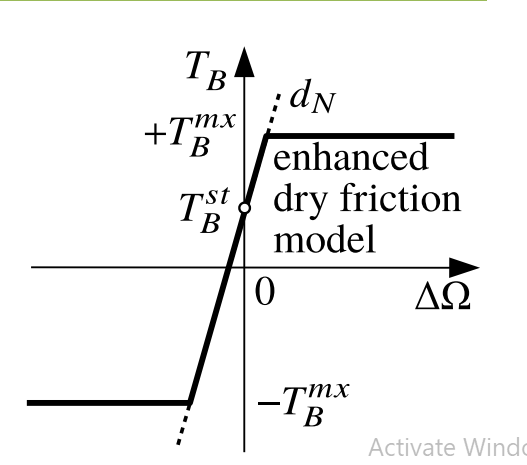 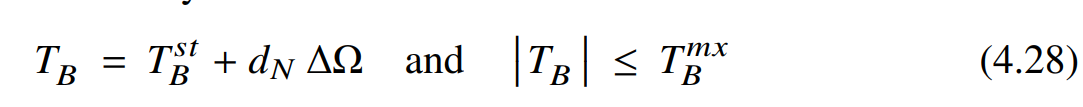

 

% derivatives
odot = (out.tq_D - out.tq_B - p.r*out.fxd) / p.theta ; % wheel

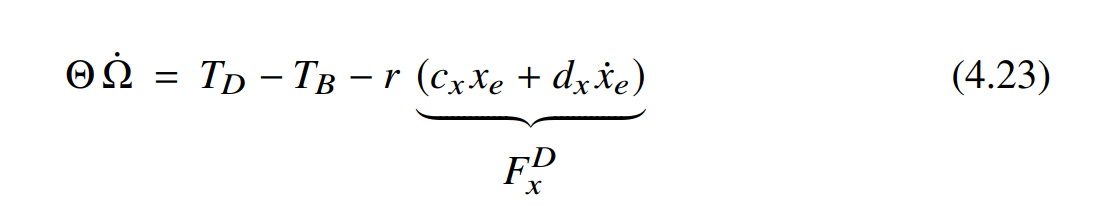

vdot = (out.fxd - p.mass*p.gravity*sin(p.al)) / p.mass; % chassis

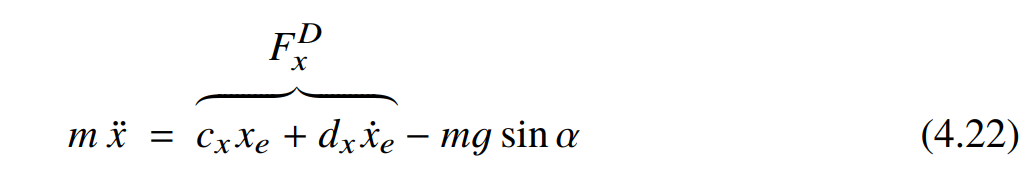

xp = [ vdot ; odot ; xedot ; v ] ; % state derivatives

end